
$$\textbf{Q1. Sampling within a Euclidean Plane}$$


(b) (5 points) Implement the algorithm described in the previous sub-question. Use it to sample N = 107 independent points (in 2D) and plot a 2D histogram of the sample. You may use the Matlab function histogram2(), e.g., with ’DisplayStyle’ as ’tile’.


$$\textbf{Algorithm}$$


Main idea is:

Calculate marginal pdf of θ

Find inverse of the CDF of obtained density function.

The obtained inverse is mapping function for θ

given θ generate random value of r by following the same process.

Equation of ellipse in polar coordinates is given by:


$$$$ r(\theta) = \frac{ab}{\sqrt{(b \cos\theta)^{2} + (a \sin\theta)^{2}}}$$$$


So PDF of marginal of θ will be: $$$\int \frac{dA}{A}$$$ = $$$f(\theta) = \frac{ab}{2\pi ({(b \cos\theta)^{2} + (a \sin\theta)^{2}})}$$$

now the random θ can be generated by taking inverse of CDF of above density function The CDF of marginal will

be:$$$\int_{0}^{\theta}\frac{ab}{2\pi ({(b \cos\theta)^{2} + (a \sin\theta)^{2}})} \,d\theta$$$

so, $$$F(\theta) = \frac{1}{2\pi} \tan^{-1}{\frac{a\tan{\theta}}{b}}$$$

Taking inverse of this:


$$$$\theta =  \tan^{-1}{\frac{b\tan{2\pi x}}{a}}$$ $$
          

(where x is random number between 0 and 1)

But range of arctan is −π/2 to π/2, So to generate random θ from −π/2 to 3π/2 we’ll take random number from 0

to 1 and map the obtained θ uniformly as: If number is less than 0.25 we’ll take negative of θ, else for number less

than 0.5 we’ll add π to negated value of θ, else if for number less than 0.75 we’ll add π to θ. In this way we can get

random values of θ.

Now given a ’θ’; probability of R = r is proportional to r; so CDF is proportional to $r^{2}$ and hence CDF inverse will

be $\sqrt{rand()}$ 

For a particular θ, range of r is 0 to $$\frac{ab}{\sqrt{(b \cos\theta)^{2} + (a \sin\theta)^{2}}}$$

so random r will be given as:$$$r = \frac{ab}{\sqrt{(b \cos\theta)^{2} + (a \sin\theta)^{2}}} \sqrt{rand()}$$$

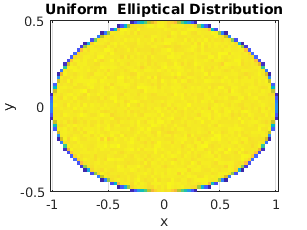

rng(0);
N = 10000000;
b = 0.5;
a = 1;
rand_num = rand(N,1);
theta = atan((b.*(tan(2.*pi.*rand_num)))./a);
for i=1:1:N
  p = rand(1,1);
  if (p < 0.25)
      theta(i,1) = -1.*theta(i,1);
  elseif(p < 0.5)
      theta(i,1) = -1.*theta(i,1) + pi;
  elseif(p < 0.75)
      theta(i,1) = theta(i,1) + pi;
  else
      theta(i,1) = theta(i,1);
  end    
end
R = (a.*b)./sqrt((b.*b.*cos(theta).*cos(theta))+(a.*a.*sin(theta).*sin(theta)));
r = R.*sqrt(rand(N,1));
x = r.*cos(theta);
y = r.*sin(theta);
histogram2(x,y,'DisplayStyle','tile');

title("Uniform  Elliptical Distribution")
xlabel("x")
ylabel("y")